clc
clear
warning("off")
close all

plotFlag = 1;
m = 1;
f = 1;
n = 1;
dataFolder = dir("Data\DataWithKneeAoR\");
dataFolder(1:2,:) = [];

dely = zeros(19,1);
dely(1) = 169;
dely(2) = -65;
dely(11) = -100;
dely(12) = -70;
dely(14) = -170;
dely(17) = -8;


config = 2;
%1:Without correction
%2:Average AoR correction
%3:Individual AoR correction
landmarkConfig = 1;
%0:Directly obtained by individual OMC data
%1:Regression equations

load("Data\Regression\KneeAoR.mat")
MMeanAorF = mean(AoRTableM{:,3:5});
MMeanAorT = mean(AoRTableM{:,6:8});
FMeanAorF = mean(AoRTableF{:,3:5});
FMeanAorT = mean(AoRTableF{:,6:8});

MMeanAorF = MMeanAorF./norm(MMeanAorF)

MMeanAorF =    -0.1212   -0.1686    0.9782


MMeanAorT = MMeanAorT./norm(MMeanAorT)

MMeanAorT =    -0.0000    0.0056    1.0000


FMeanAorF = FMeanAorF./norm(FMeanAorF)

FMeanAorF =    -0.1722   -0.0574    0.9834


FMeanAorT = FMeanAorT./norm(FMeanAorT)

FMeanAorT =    -0.0000    0.0018    1.0000



load("Data\Regression\RegLandmarkPos.mat")
load("Data\Regression\LandmarkPos.mat")



i = 1

Average AoR correction


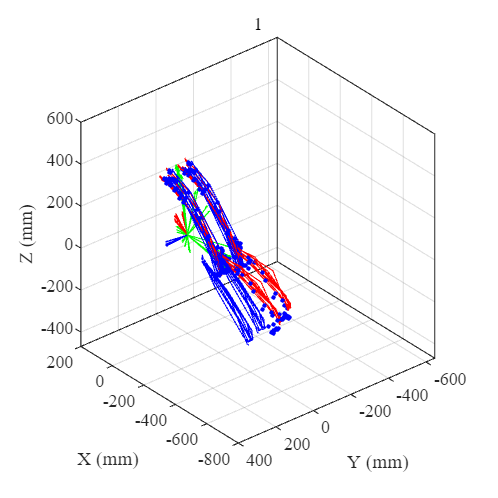

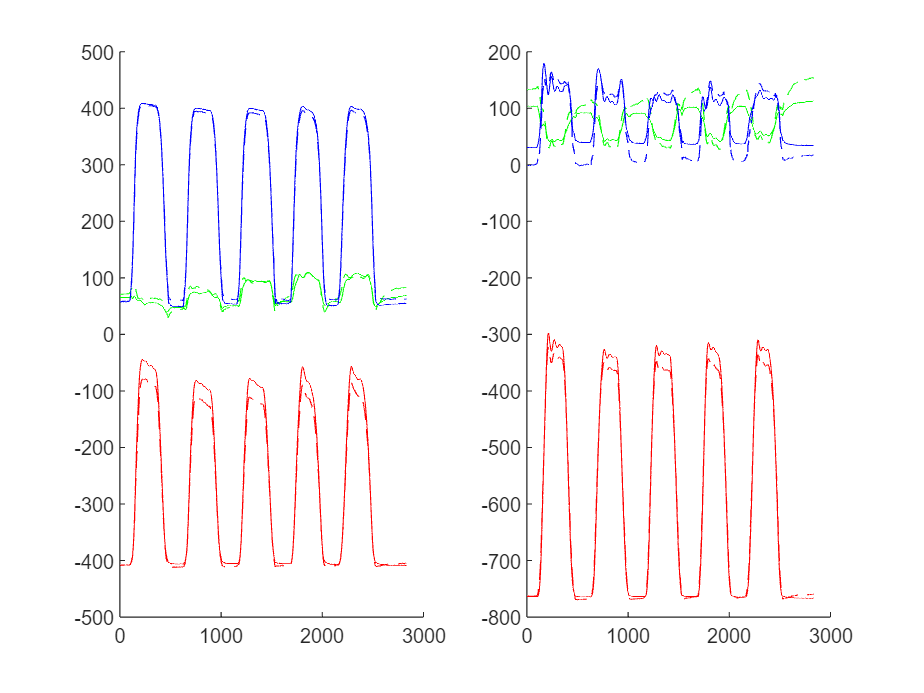

i = 2

Average AoR correction


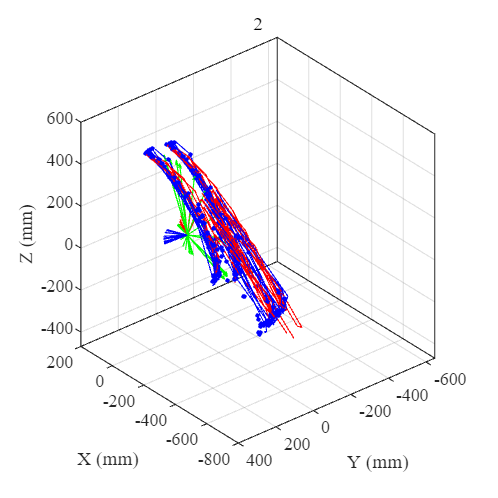

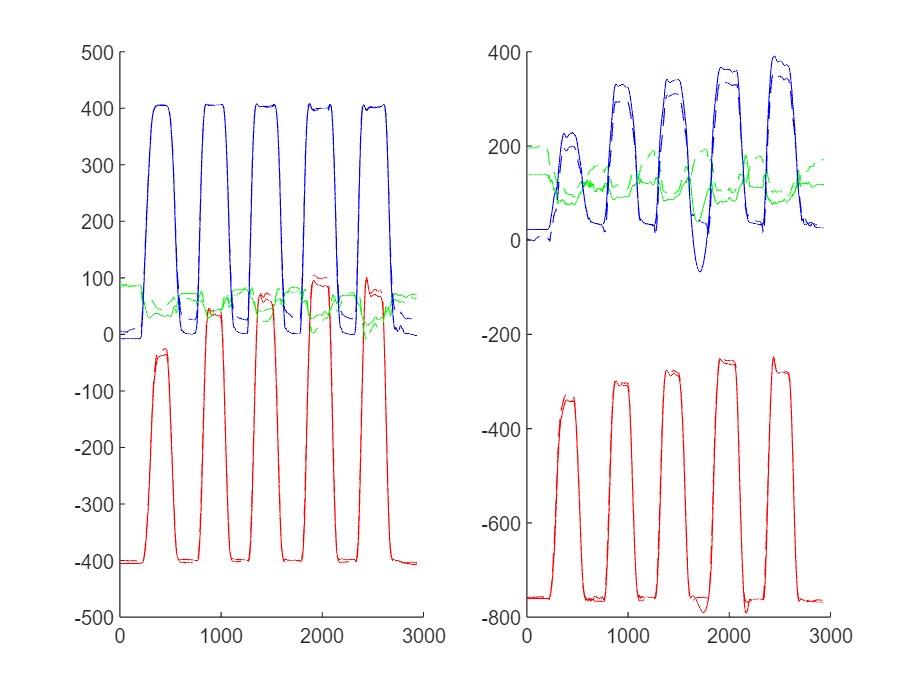

i = 3

Average AoR correction


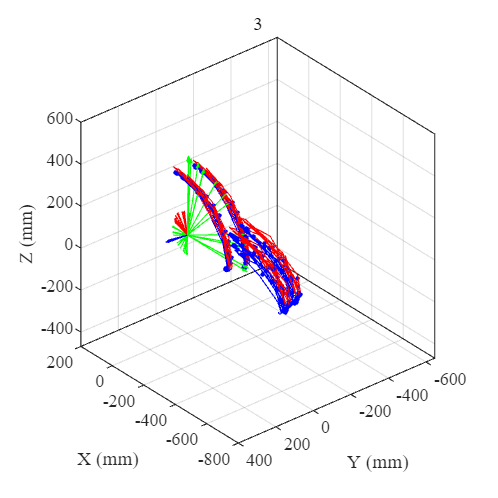

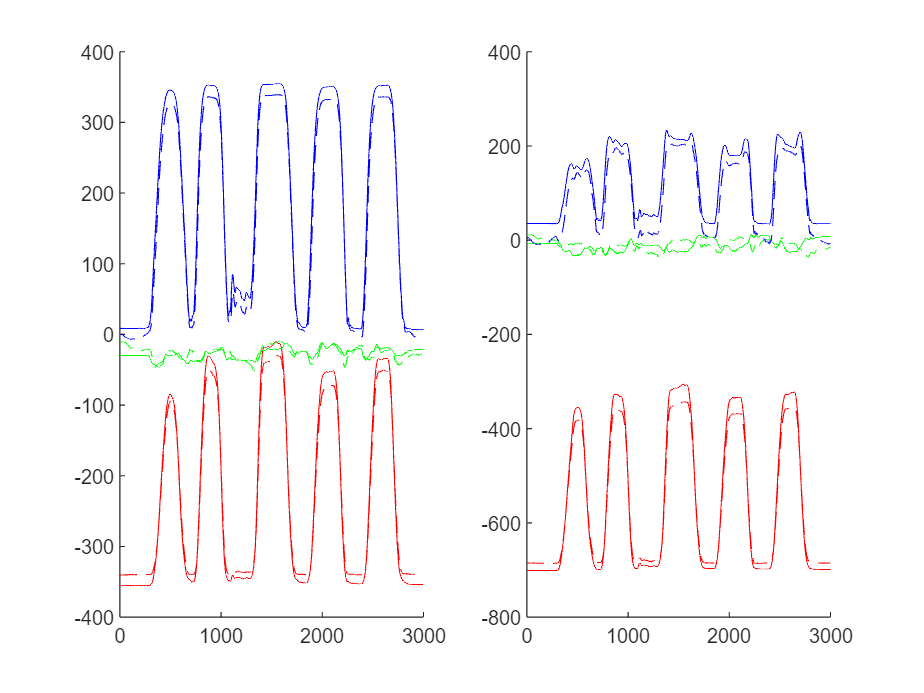

i = 4

i = 5

i = 6

Average AoR correction


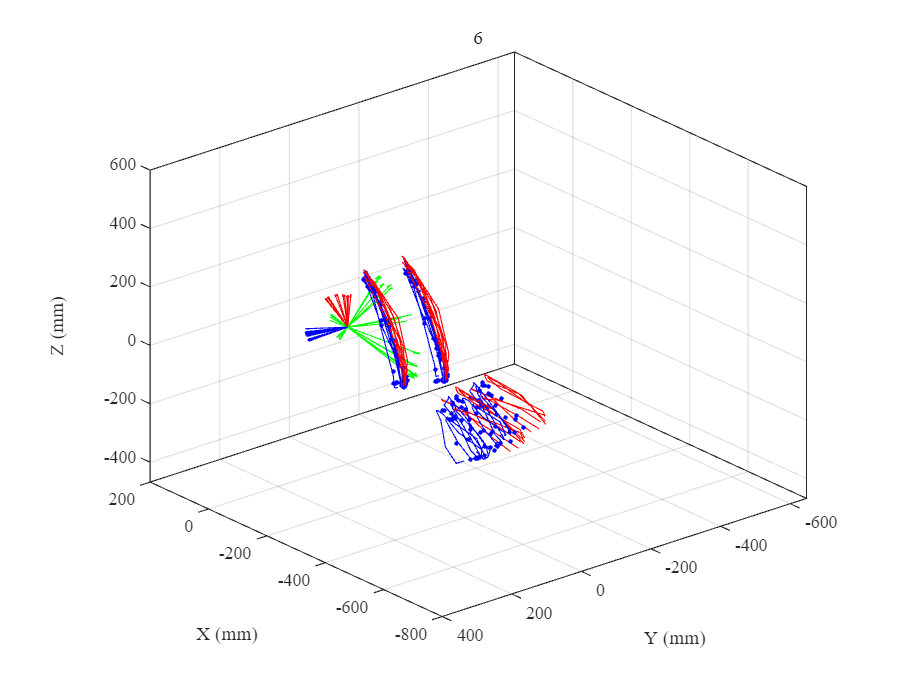

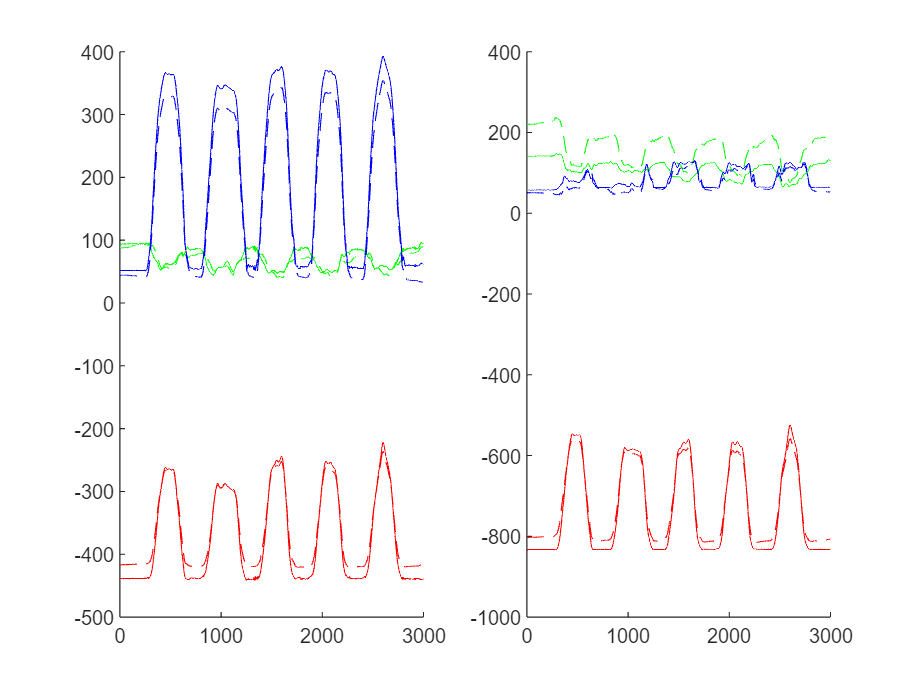

i = 7

Average AoR correction


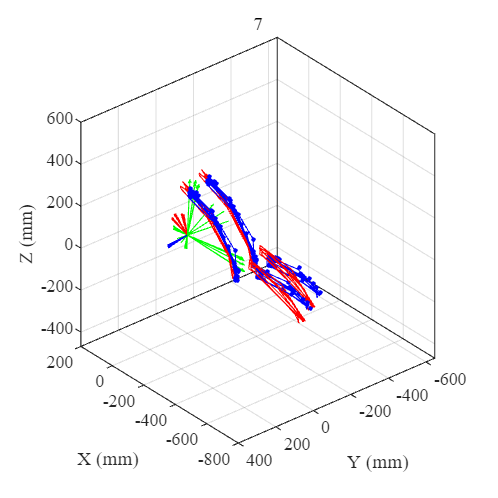

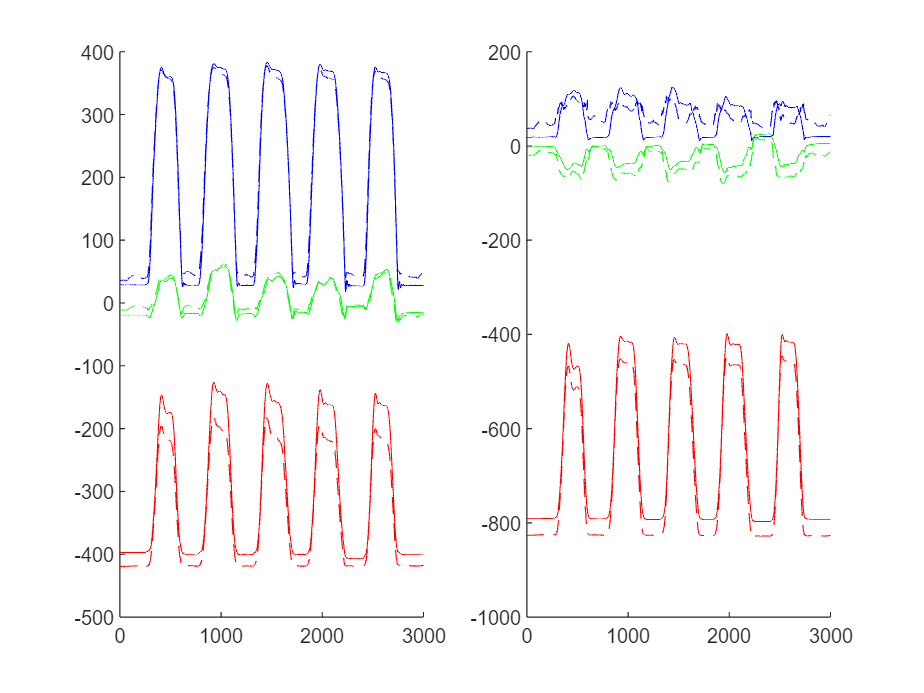

i = 8

i = 9

Average AoR correction


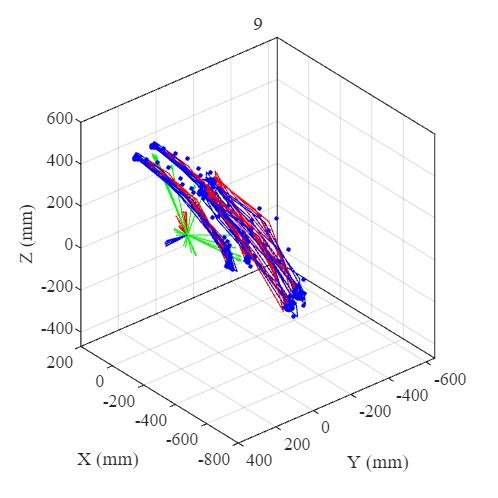

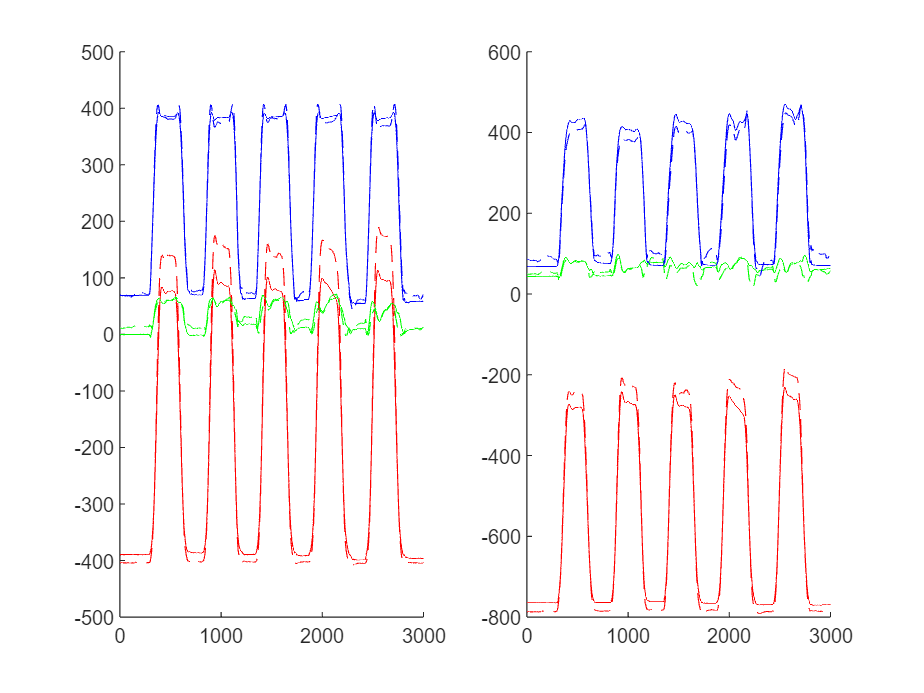

i = 10

Average AoR correction


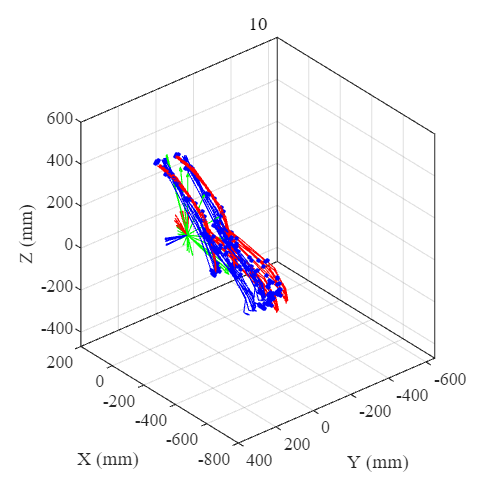

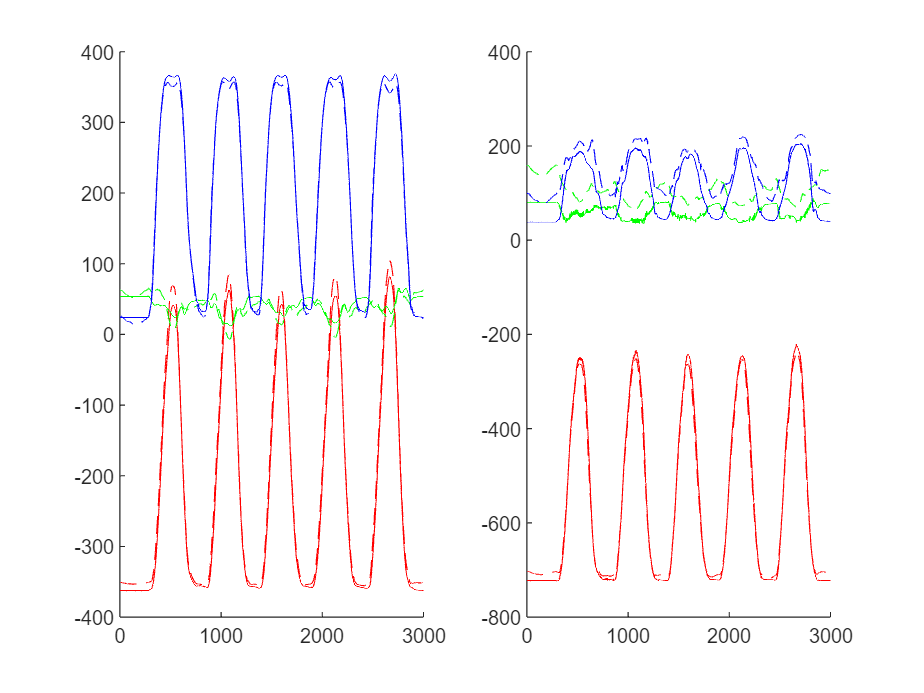

i = 11

Average AoR correction


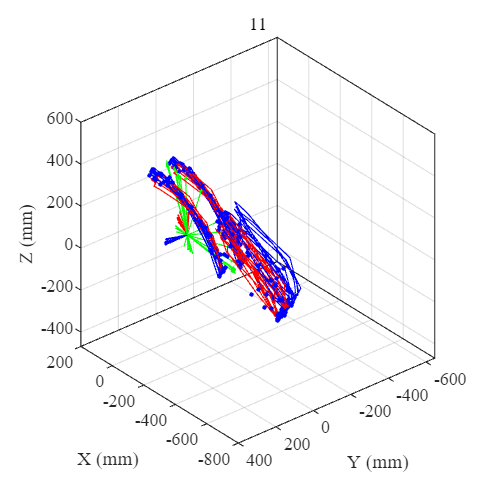

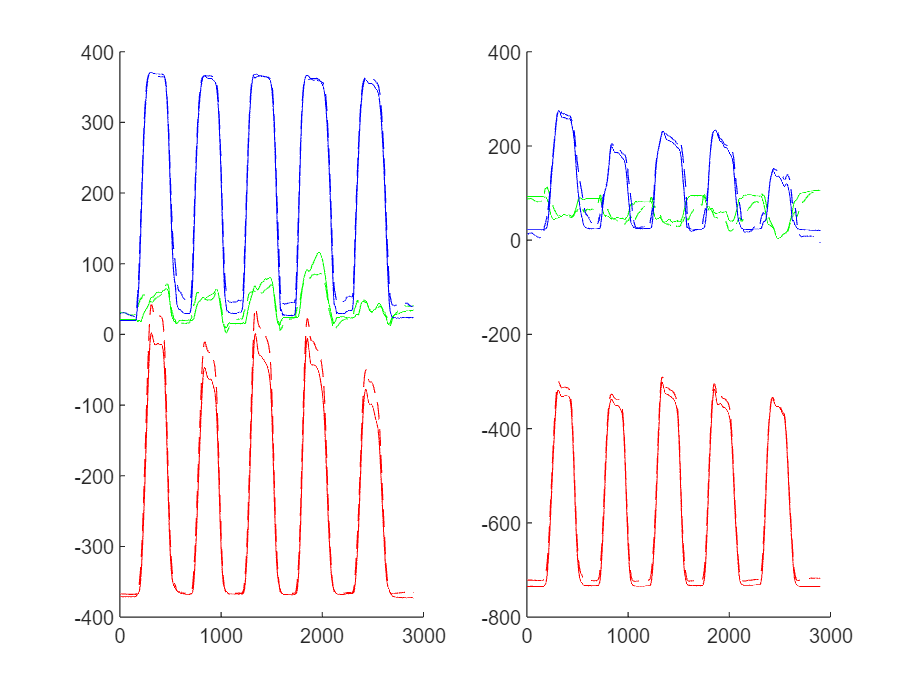

i = 12

Average AoR correction


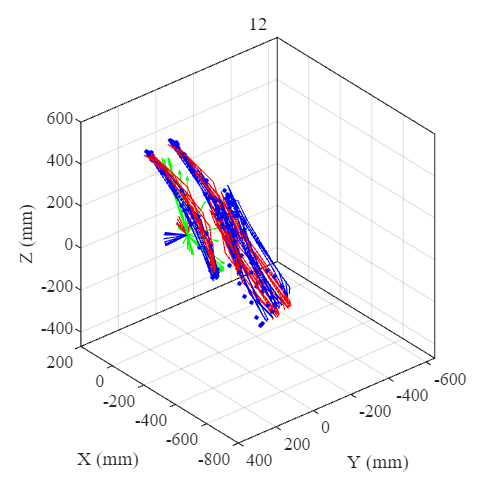

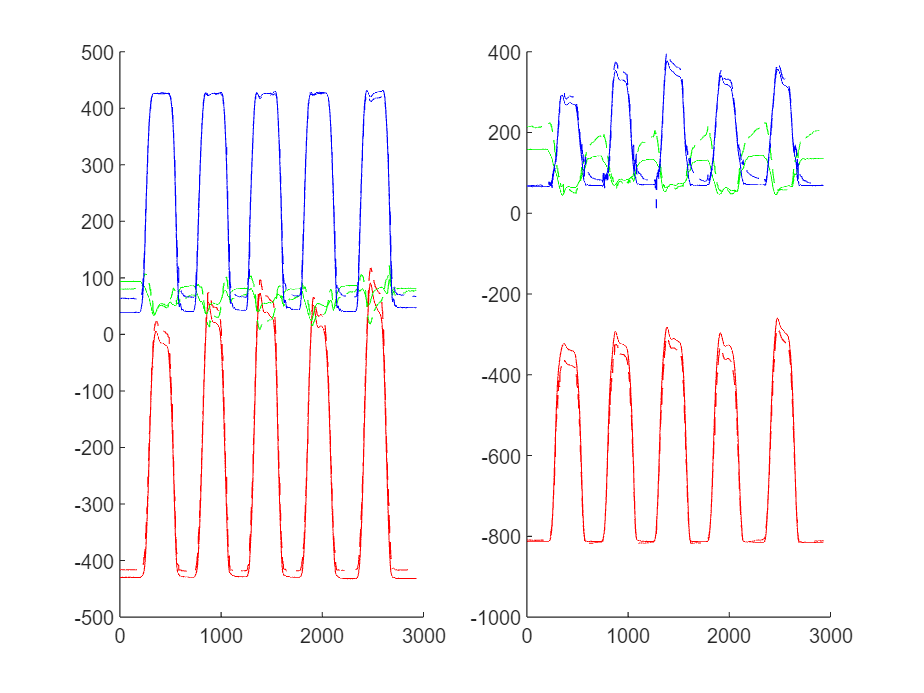

i = 13

Average AoR correction


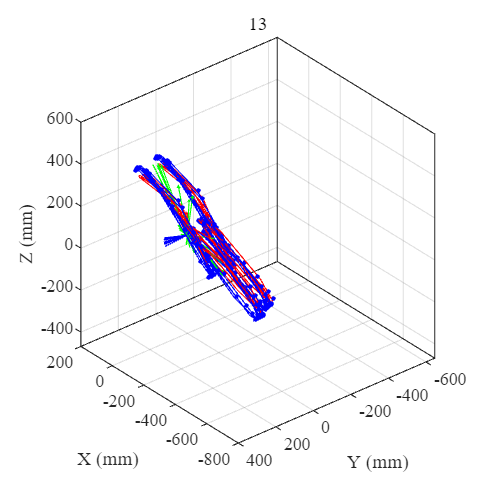

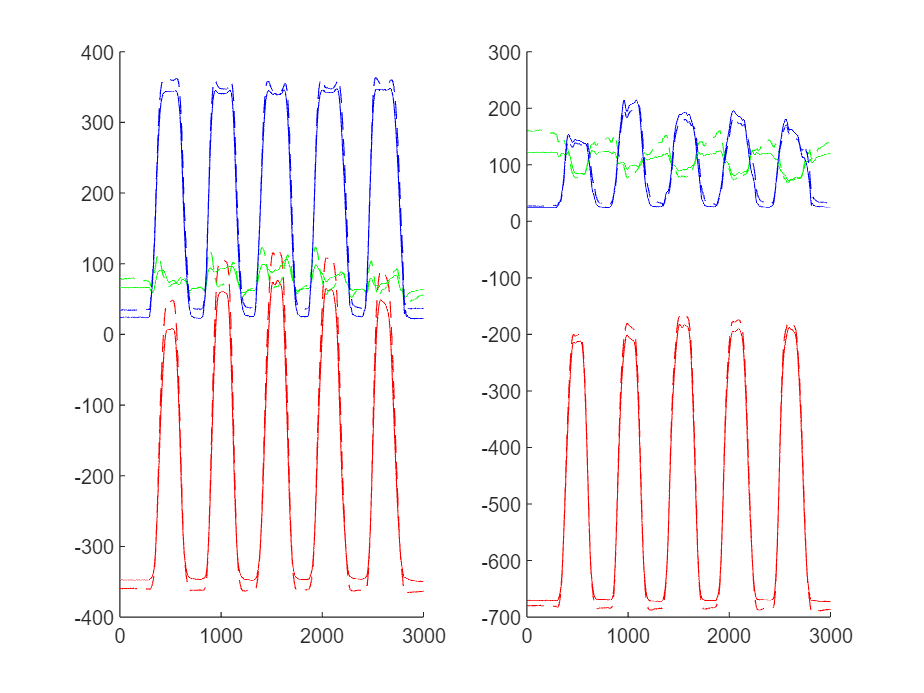

i = 14

Average AoR correction


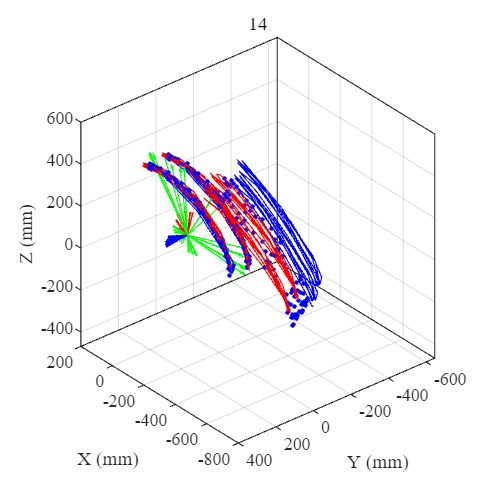

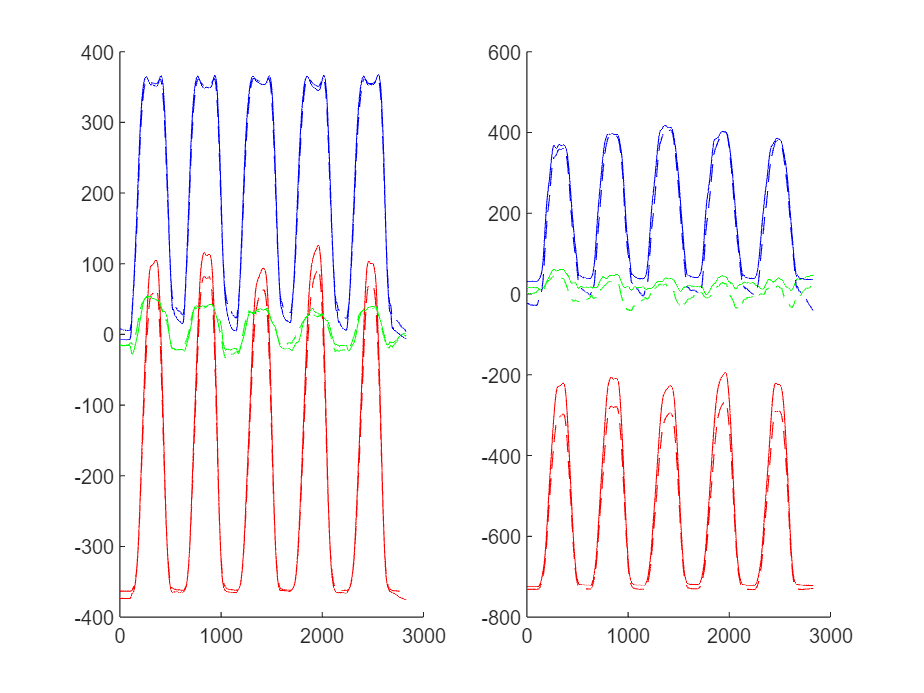

i = 15

Average AoR correction


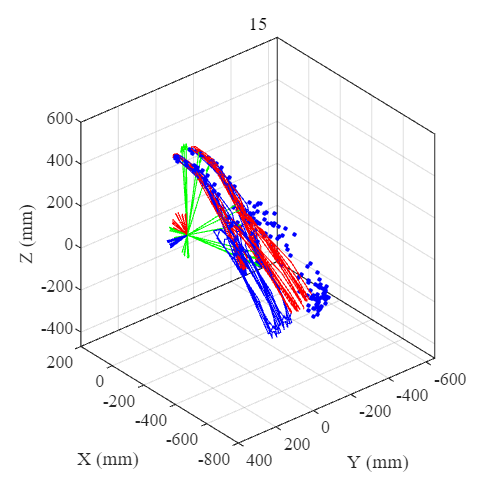

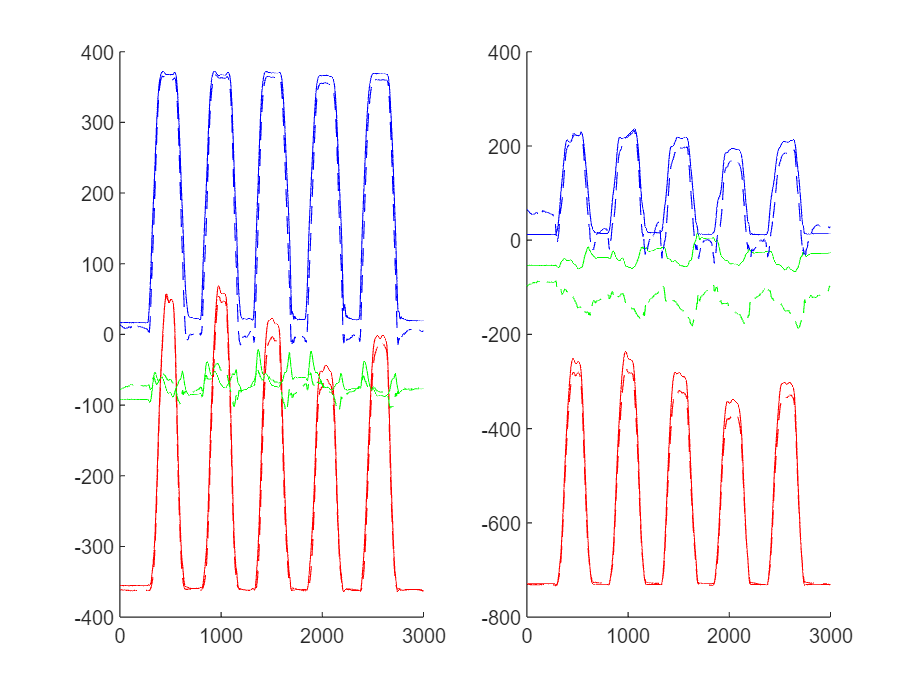

i = 16

Average AoR correction


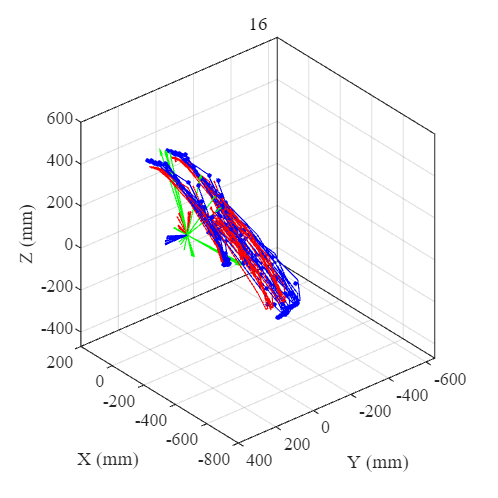

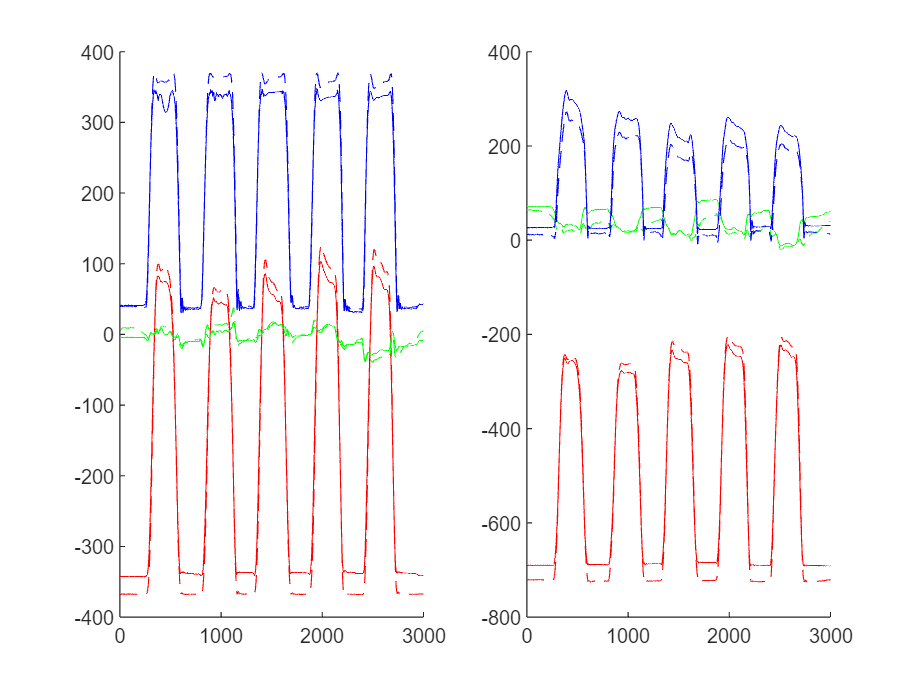

i = 17

Average AoR correction


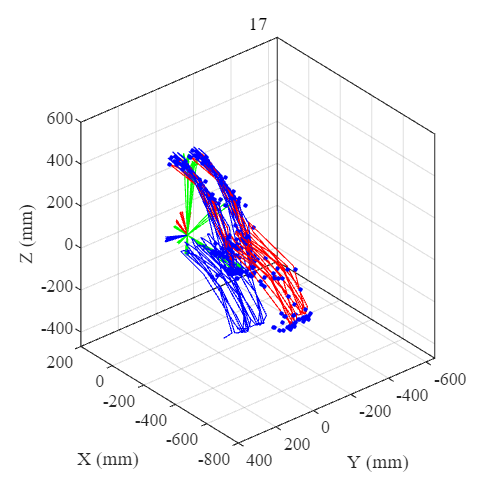

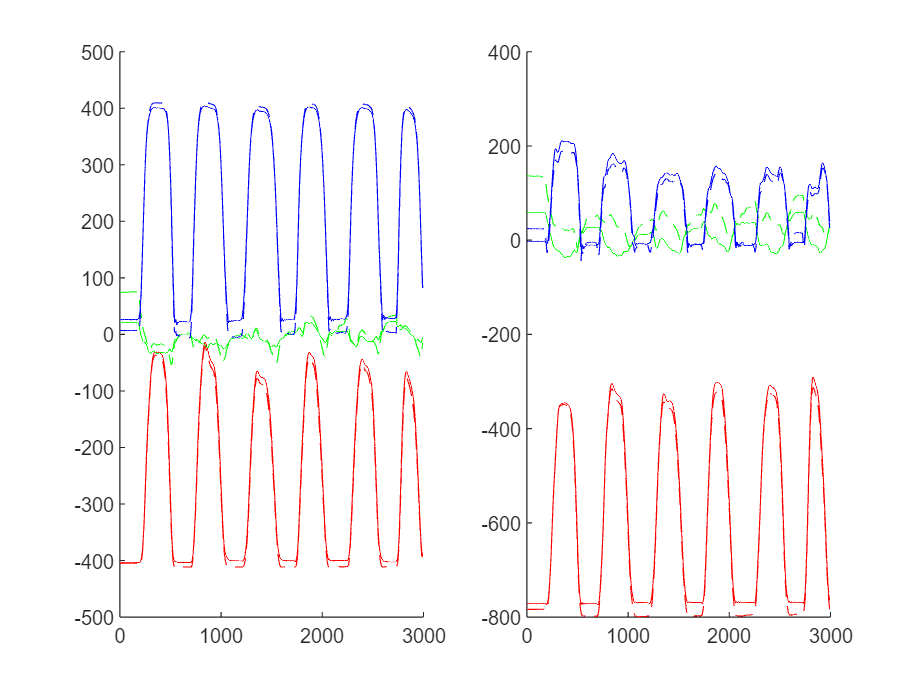

i = 18

Average AoR correction


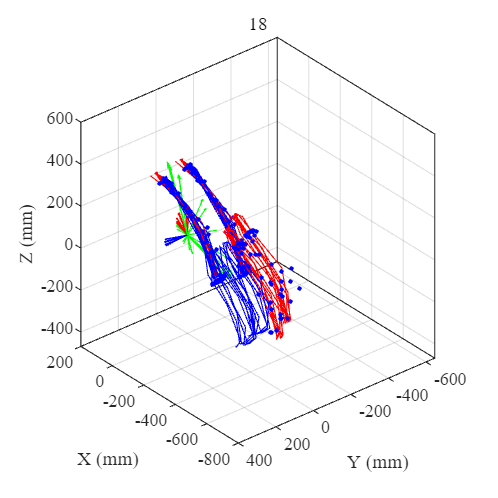

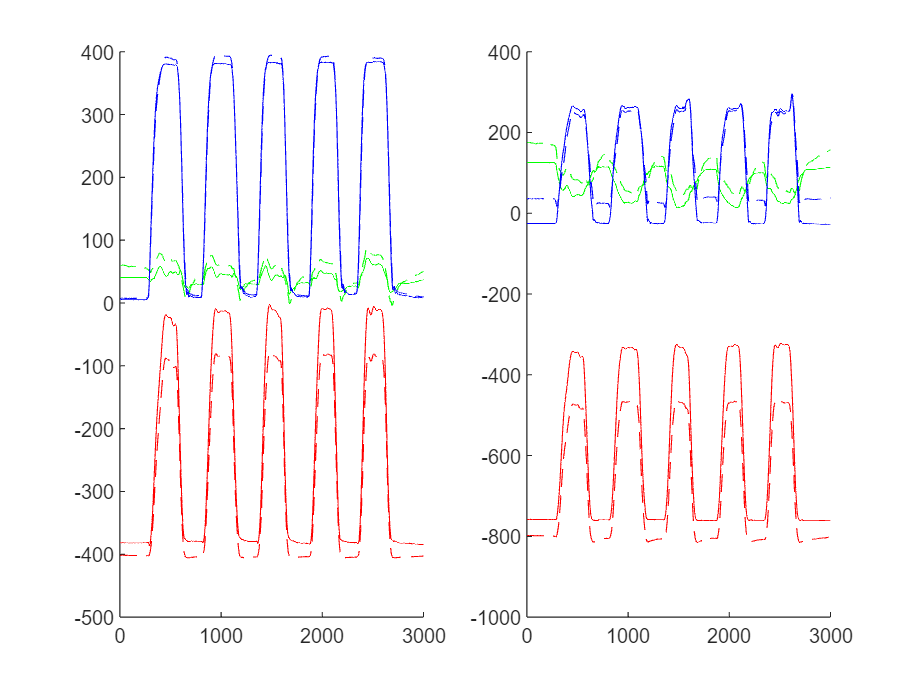

i = 19

Average AoR correction


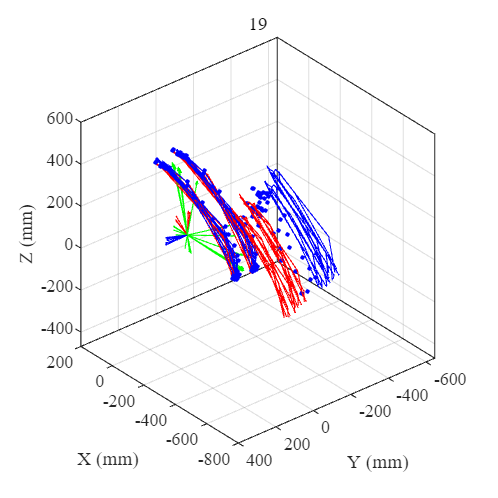

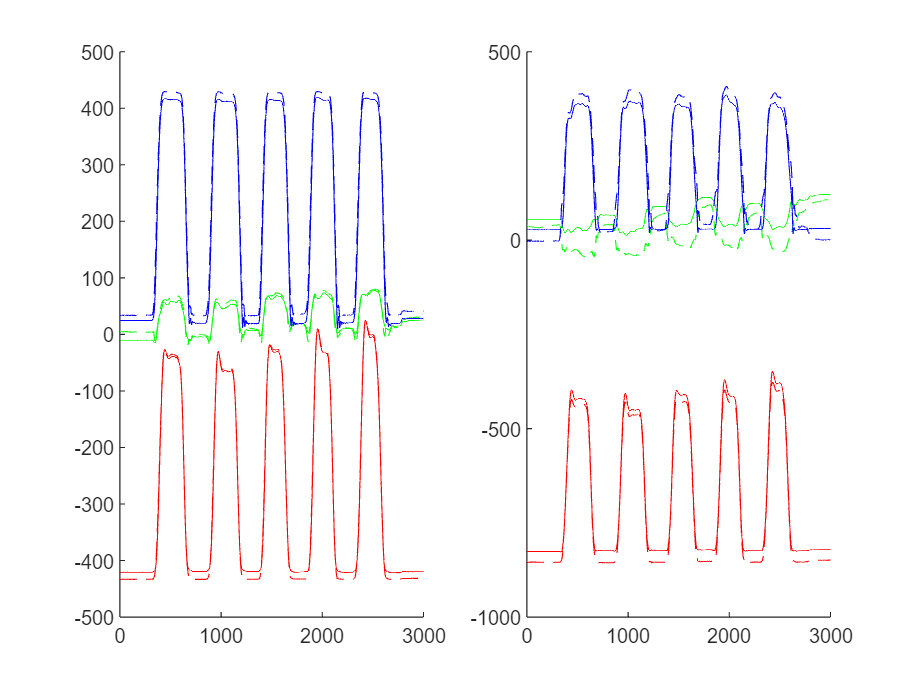



for i = 1:19
    clear imcData
    i
    dataFileName = dataFolder(i).folder+"\"+dataFolder(i).name;
    load(dataFileName)

    if ~size(imcData.REFM,1)
        continue
    end

    Gender = omcData.Gender;
    SubjectID = omcData.SubjectID;
    if Gender == 'm'
        if landmarkConfig
            id = find(regMarkTableM.SubjectID==SubjectID);
            markPos = regMarkTableM{id,:};
        else
            id = find(MarkTableM.SubjectID==SubjectID);
            markPos = MarkTableM{id,:};
        end
    else
        if landmarkConfig
            id = find(regMarkTableF.SubjectID==SubjectID);
            markPos = regMarkTableF{id,:};
        else
            id = find(MarkTableF.SubjectID==SubjectID);
            markPos = MarkTableF{id,:};
        end
    end

    imcData.REFMInit = markPos(2:4)';
    imcData.REFLInit = markPos(5:7)';
    imcData.RMMInit = markPos(8:10)';
    imcData.RLMInit = markPos(11:13)';

    imcData.getMarkTrajectories;

    omcData.getInitFrame;
    imcData.getInitFrame;
    RotationInit = omcData.ReferenceFrameInit/imcData.ReferenceFrameInit;
    imcData.rotateReferenceFrame(RotationInit)


    if dely(i)>0
        omcData.selectRange(dely(i),size(omcData.REFM));
    elseif dely(i)<0
        imcData.selectRange(-dely(i),size(imcData.REFM));
    else
    end

    if size(omcData.REFM,1)>size(imcData.REFM,1)
        omcData.selectRange(1,size(imcData.REFM));
    else
        imcData.selectRange(1,size(omcData.REFM));
    end

    if plotFlag
        ploter = Ploter(omcData.SubjectID);
        ploter.plotInit
        ploter.plotMarkerTrajectories(omcData,'r-',1,50,2500)
        ploter.plotMarkerTrajectories(imcData,'b-',1,50,2500)
        ploter.plotFemoralFrame(omcData,1,50,1000)
        %         ploter.plotFemoralFrameClusterFrame(omcData,1,50,1000)
        %         ploter.plotTibiaFrameClusterFrame(omcData,1,100,500)
%                 ploter.plotTibiaFrame(omcData,1,100,1000)
        %         ploter.plotKneeAoR(omcData.RKneeAoR_F_Selected(:,2:5))
    end

    switch config
        case 1
            % Without correction
        case 2
            % Average AoR correction
            disp('Average AoR correction')
            if Gender == m
                imcData.getFemoralFrameCorrRotm(MMeanAorF);
                imcData.getTibiaFrameCorrRotm(MMeanAorT);
            else
                imcData.getFemoralFrameCorrRotm(FMeanAorF);
                imcData.getTibiaFrameCorrRotm(FMeanAorT);
            end
            imcData.rotateFemoralFrame(imcData.RotmF);
            imcData.rotateTibiaFrame(imcData.RotmT);
%             imcData.rotateTibiaFrameInFemoralFrame(imcData.RotmT);

%             imcData.rotateTibiaFrame(r)
%             imcData.rotateTibiaFrame(eul2rotm([0,0,20]./180*pi));
%             imcData.rotateTibiaFrameInFemoralFrame(eul2rotm([30,0,0]./180*pi));
%             imcData.rotateTibiaFrame(eul2rotm([0,0,-30]./180*pi));

                      
            imcData.getMarkTrajectories;
            imcData.getInitFrame;
            RotationInit = omcData.ReferenceFrameInit/imcData.ReferenceFrameInit;
            imcData.rotateReferenceFrame(RotationInit)
%             r = imcData.RTibiaRotm{1}'*omcData.RTibiaRotm{1}
%             imcData.rotateTibiaFrame(r);  
% 
%             imcData.getMarkTrajectories;

%             imcData.rotateTibiaFrame(r); 


            
        case 3
            disp('Individual AoR correction')
            imcData.getFemoralFrameCorrRotm(omcData.MeanRKneeAoR_F);
            imcData.getTibiaFrameCorrRotm(omcData.MeanRKneeAoR_T);
            imcData.rotateFemoralFrame(imcData.RotmF);            
            imcData.rotateTibiaFrame(imcData.RotmT);
%             imcData.rotateTibiaFrame

%             EulF = rotm2eul(imcData.RotmF);
%             RotmF = eul2rotm([0,0,EulF(3)]);
%             EulT = rotm2eul(imcData.RotmT);
%             RotmT = eul2rotm([0,0,EulT(3)]);
%             imcData.rotateFemoralFrame(RotmF);            
%             imcData.rotateTibiaFrame(RotmT);



            a = imcData.RFemoralRotm{1,1}(:,2);
            b = imcData.RTibiaRotm{1,1}(:,2);
            imcangle = acos(dot(a,b))./pi*180;

            a = omcData.RFemoralRotm{1,1}(:,2);
            b = omcData.RTibiaRotm{1,1}(:,2);
            omcangle = acos(dot(a,b))./pi*180;


            imcData.getMarkTrajectories;
            imcData.getInitFrame;
            RotationInit = omcData.ReferenceFrameInit/imcData.ReferenceFrameInit;
            imcData.rotateReferenceFrame(RotationInit)

    end
    omcData.getEul;
    imcData.getEul;



    max(imcData.REFM(3));
    topFrame = find(imcData.REFM(:,3)==max(imcData.REFM(:,3)));
    a = [0,0,-1];
    b = imcData.RFemoralRotm{topFrame(1),1}(:,2);
    ROMF = 180-acos(dot(a,b)/(norm(a)*norm(b)))./pi*180;
    a = [0,0,-1];
    b = imcData.RTibiaRotm{1,1}(:,2);
    ROMT = acos(dot(a,b)/(norm(a)*norm(b)))./pi*180;

    if plotFlag
        ploter.plotMarkerTrajectories(imcData,'b.',1,50,2500)
    end


    if plotFlag
        figure
        subplot(1,2,1)
        hold on
        plot(omcData.REFM(:,1),'r')
        plot(imcData.REFM(:,1),'r--')
        plot(omcData.REFM(:,2),'g')
        plot(imcData.REFM(:,2),'g--')
        plot(omcData.REFM(:,3),'b')
        plot(imcData.REFM(:,3),'b--')
        hold off
        subplot(1,2,2)
        hold on
        plot(omcData.RMM(:,1),'r')
        plot(imcData.RMM(:,1),'r--')
        plot(omcData.RMM(:,2),'g')
        plot(imcData.RMM(:,2),'g--')
        plot(omcData.RMM(:,3),'b')
        plot(imcData.RMM(:,3),'b--')
        hold off
    end




    for i = 1:size(imcData.REFM,1)
        ErrorFemoralRotm{i,1} = imcData.RFemoralRotm{i,1}/omcData.RFemoralRotm{i,1};
        ErrorTibiaRotm{i,1} = imcData.RTibiaRotm{i,1}/omcData.RTibiaRotm{i,1};
        ErrorEul(i,1:3) = rotm2eul(ErrorFemoralRotm{i,1});
        ErrorEul(i,4:6) = rotm2eul(ErrorTibiaRotm{i,1});
        a = imcData.RFemoralRotm{i,1}(:,2);
        b = omcData.RFemoralRotm{i,1}(:,2);
        angleF(i,1) = acos(dot(a,b));
        a = imcData.RTibiaRotm{i,1}(:,2);
        b = omcData.RTibiaRotm{i,1}(:,2);
        angleT(i,1) = acos(dot(a,b));
    end

    ErrorEul(any(isnan(ErrorEul), 2),:) = [];
    rmsErrorEul = rms(ErrorEul)./pi*180;

    rmsAngleF = rms(angleF)/pi*180;
    rmsAngleT = rms(angleT)/pi*180;

    error = Error(imcData,omcData);

    RMSArray(n,1) = SubjectID;
    RMSArray(n,2:5) = error.RMS;

    CorrArray(n,1) = SubjectID;
    CorrArray(n,2:13) = error.pearson;

    ICCArray(n,1) = SubjectID;
    ICCArray(n,2:13) = error.icc;

    if Gender == 'm'
        RMSArrayM(m,1) = SubjectID;
        RMSArrayM(m,2:5) = error.RMS;
        RMSPercentArrayM(m,2:5) = error.RMS./omcData.RKneeCenterInit*100;
        RMSPercentArrayM(m,2:5) = error.RMS./(omcData.RAnkleCenterInit+omcData.RKneeCenterInit)*100;
        CorrArrayM(m,1) = SubjectID;
        CorrArrayM(m,2:13) = error.pearson;

        ICCArrayM(m,1) = SubjectID;
        ICCArrayM(m,2:13) = error.icc;
        RMSAngleM(m,1) =  rmsAngleF;
        RMSAngleM(m,2) =  rmsAngleT;
        RMSAnglePercentM(m,1) =  rmsAngleF/ROMF*100;
        RMSAnglePercentM(m,2) =  rmsAngleT/ROMT*100;

        rmsErrorEulM(m,1:6) = rmsErrorEul;
        rmsErrorEulM(m,7) = SubjectID;

%         rmsErrorEulPercentM(m,1:6) = rmsErrorEul./([imcData.ROMF,imcData.ROMT]./pi*180);
%         rmsErrorEulPercentM(m,1:6) = rmsErrorEul./([imcData.ROMF,imcData.ROMT]./pi*180);
        
%         ROMM(m,:) = [imcData.ROMF]



        m = m+1;
    else
        RMSArrayF(f,1) = SubjectID;
        RMSArrayF(f,2:5) = error.RMS;
        RMSPercentArrayF(f,2:5) = error.RMS./omcData.RKneeCenterInit*100;
        RMSPercentArrayF(f,2:5) = error.RMS./(omcData.RAnkleCenterInit+omcData.RKneeCenterInit)*100;

        CorrArrayF(f,1) = SubjectID;
        CorrArrayF(f,2:13) = error.pearson;

        ICCArrayF(f,1) = SubjectID;
        ICCArrayF(f,2:13) = error.icc;

        RMSAngleF(f,1) =  rmsAngleF;
        RMSAngleF(f,2) =  rmsAngleT;
        RMSAnglePercentF(f,1) =  rmsAngleF/ROMF*100;
        RMSAnglePercentF(f,2) =  rmsAngleT/ROMT*100;

        rmsErrorEulF(f,1:6) = rmsErrorEul;
        rmsErrorEulF(f,7) = SubjectID;
%         ROMF(f,:) = [imcData.ROMF]
%         rmsErrorEulPercentF(f,1:6) = rmsErrorEul./([imcData.ROMF,imcData.ROMT]./pi*180);
        f = f+1;
    end
    n = n+1;

    ROMFArray(n) = ROMF;
    ROMTArray(n) = ROMT;


    %     figure
    %     hold on
    %     plot(imcData.REFM(:,3),'b')
    %     plot(omcData.REFM(:,3),'r')
%     save("Data\ProcessedDataAAoR\"+"Data"+num2str(omcData.SubjectID,"%02d"),"omcData","imcData")
%     save("Data\ProcessedDataIAoR\"+"Data"+num2str(omcData.SubjectID,"%02d"),"omcData","imcData")
%     save("Data\ProcessedDataUsingOMC\"+"Data"+num2str(omcData.SubjectID,"%02d"),"omcData","imcData")
%     save("Data\ProcessedDataUsingReg\"+"Data"+num2str(omcData.SubjectID,"%02d"),"omcData","imcData")
end

RMSTable = error.getRMSTable(RMSArray);
RMSTableM = error.getRMSTable(RMSArrayM);
RMSTableF = error.getRMSTable(RMSArrayF);


RMSTable = [RMSTableM;RMSTableF;RMSTable];
RMSTable.Properties.RowNames = {'Male','Female','Total'}

RMSTable = 3×4 table
                  REFM            REFL             RMM              RLM     
              ____________    ____________    _____________    _____________

    Male      {'26.5±6.3'}    {'23.4±7.4'}    {'53.3±10.5'}    {'55.1±13.0'}
    Female    {'32.6±9.1'}    {'31.9±9.6'}    {'57.3±27.5'}    {'56.0±27.4'}
    Total     {'30.4±8.5'}    {'28.7±9.5'}    {'55.8±22.2'}    {'55.7±22.5'}




RMSPercentTableM = error.getRMSTable(RMSPercentArrayM)

RMSPercentTableM = 1×4 table
       REFM           REFL            RMM            RLM    
    ___________    ___________    ___________    ___________

    {'3.3±0.8'}    {'2.9±0.9'}    {'6.6±1.2'}    {'6.8±1.4'}


RMSPercentTableF = error.getRMSTable(RMSPercentArrayF)

RMSPercentTableF = 1×4 table
       REFM           REFL            RMM            RLM    
    ___________    ___________    ___________    ___________

    {'4.4±1.1'}    {'4.3±1.2'}    {'7.6±3.6'}    {'7.5±3.6'}


函数或变量 'ROMM' 无法识别。

% mean(rmsErrorEulPercentM*100)
% std(rmsErrorEulPercentM*100)
% 
% mean(rmsErrorEulPercentF*100)
% std(rmsErrorEulPercentF*100)


EulError = mean([rmsErrorEulM(:,1:6);rmsErrorEulM(:,1:6)]);
EulErrorSD = std([rmsErrorEulM(:,1:6);rmsErrorEulM(:,1:6)]);

% EulErrorPercent = mean([rmsErrorEulPercentM;rmsErrorEulPercentF]*100);
% EulErrorPercentSD = std([rmsErrorEulPercentM;rmsErrorEulPercentF]*100);


 for i = 1:6
        EulErrorTable{i} = [num2str(EulError(i),'%.1f'),char(177),num2str(EulErrorSD(i),'%.1f')];
        EulErrorPercentTable{i} = [num2str(EulErrorPercent(i),'%.1f'),char(177),num2str(EulErrorPercentSD(i),'%.1f')];

end
EulErrorTable
EulErrorPercentTable



EulErrorM = mean(rmsErrorEulM(:,1:6))
EulErrorF = mean(rmsErrorEulF(:,1:6))


AngleErrorM = mean(RMSAngleM)
std(RMSAngleM)
AngleErrorF = mean(RMSAngleF)
std(RMSAngleF)



MeanRMSAnglePercentM = mean(RMSAnglePercentM)
std(RMSAnglePercentM)
MeanRMSAnglePercentF = mean(RMSAnglePercentF)
std(RMSAnglePercentF)


rTable = error.getRTable(CorrArray)



Corr = mean(CorrArray);
CorrM = mean(CorrArrayM);
CorrF = mean(CorrArrayF);

% Corr = [CorrM;CorrF;Corr];

Corr(:,1) = [];
CorrX = [min(Corr(1:3:12)),max(Corr(1:3:12))]
CorrY = [min(Corr(2:3:12)),max(Corr(2:3:12))]
CorrZ = [min(Corr(3:3:12)),max(Corr(3:3:12))]



% ICCArray(:,1) = [];
ICCX = [min(ICCArray(:,2:3:13)),max(ICCArray(:,2:3:13))];
ICCY = [min(ICCArray(:,3:3:13)),max(ICCArray(:,3:3:13))];
ICCZ = [min(ICCArray(:,4:3:13)),max(ICCArray(:,4:3:13))];


ICCX = [mean(ICCArray(:,2:3:13))]
ICCY = [mean(ICCArray(:,3:3:13))]
ICCZ = [mean(ICCArray(:,4:3:13))]
mean(ICCX)
mean(ICCY)
mean(ICCZ)


